clearvars;
h = 0.06;
T = 0.6;
time = (0:h:T);


U = zeros(round(T/h)+2,1);
U(1) = exp(h);
U(2) = 1;

for i = (3:round(T/h)+2)
    U(i) = TwoStep(U(i-2),U(i-1),h,@specFun);
  
end

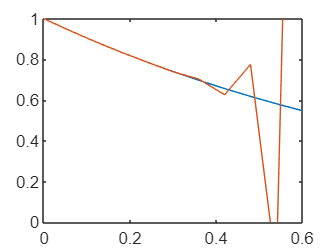

Uexact = exp(-time);
Uapprox = U(2:end);
plot(time,Uexact);
hold on
plot(time,Uapprox);
ylim([0,1])
hold off

h = 1/5;
n = (1:100);
tn = (n-1)*h;
U = zeros(size(n));
U(1)= 100;
for i = n
    U(i+1) = (1-8*h)*U(i)+h*(120*exp(-tn(i)/8) + 40);
end

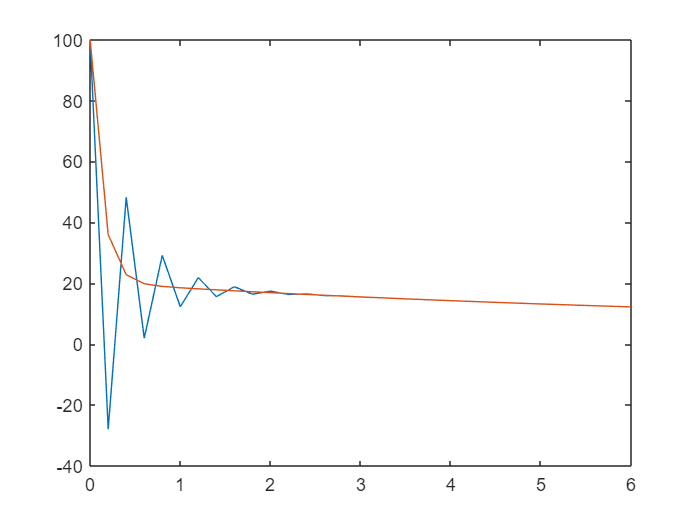

U_exact = 1675/21 * exp(-8*tn)+320/21 * exp(-tn/8)+5;

plot(tn,U(1:end-1));
hold on
plot(tn,U_exact)
hold off

xlim([0,6]);

h = 1/5;
n = (1:100);
tn = (n-1)*h;
U = zeros(size(n));
U(1)= 100;
for i = n(1:99)
    U(i+1) = 1/(1+8*h)*(U(i) + h*(120*exp(-tn(i+1)/8)+40));
end

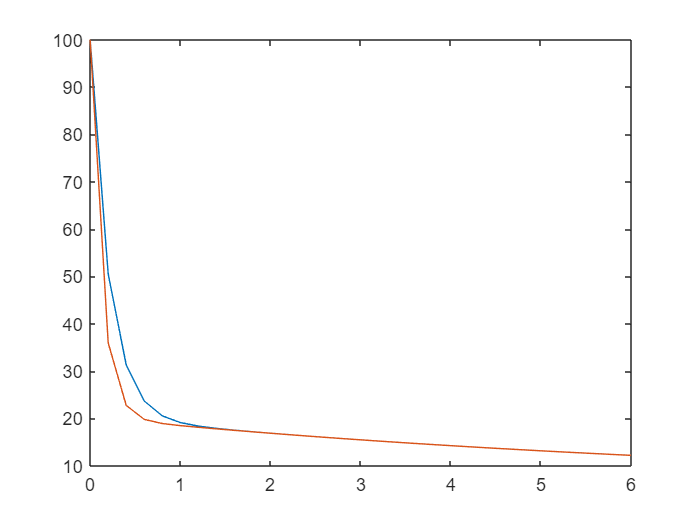

U_exact = 1675/21 * exp(-8*tn)+320/21 * exp(-tn/8)+5;


plot(tn,U);
hold on
plot(tn,U_exact)
hold off

xlim([0,6]);

h = 1/3;
n = (1:100);
t = (n-1)*h;
U = zeros(size(n));
U(1) = 100;

UR = zeros(size(n));
UR(1) = 100;

UR(2) = RK2(t(1),U(1),@fun,h);
U(2) = RK2(t(1),U(1),@fun,h);
for i = n(2:99)
    U(i+1) = (4*U(i)-U(i-1) +80*h *(3*exp(-t(i+1)/8)+1)) /(3+16*h);
    UR(i+1) = RK2(t(i),UR(i),@fun,h);
end

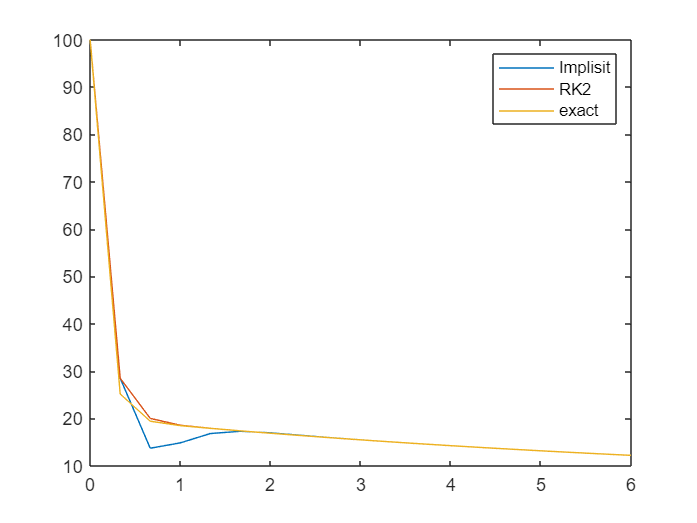

U_exact = 1675/21 * exp(-8*t)+320/21 * exp(-t/8)+5;

plot(t,U);
hold on
plot(t,UR);
plot(t,U_exact);
legend(["Implisit","RK2","exact"])
hold off

xlim([0,6]);

N = 2.^(6:15);
err_ex =zeros(size(N));
err_im=zeros(size(N));

err_BDF2 = zeros(size(N));
err_RK2 = zeros(size(N));
T = 6;
j=1;
for n = N
    
    
    h = T/(n-1);
    t = (0:h:T);
    U_exact = 1675/21 * exp(-8*t)+320/21 * exp(-t/8)+5;

    U_ex = zeros(1,n);
    U_ex(1) =100;
    for i = (1:n-1)
        U_ex(i+1) = (1-8*h)*U_ex(i)+h*(120*exp(-t(i)/8) + 40);
    end
    err_ex(j) = max(abs(U_ex -U_exact));

    U_im = zeros(1,n);
    U_im(1) = 100;
    for i = (1:n-1)
        U_im(i+1) = 1/(1+8*h)*(U_im(i) + h*(120*exp(-t(i+1)/8)+40));
    end
    err_im(j) = max(abs(U_im -U_exact));

    
    BDF2 = zeros(1,n);
    BDF2(1) = 100;

    UR = zeros(1,n);
    UR(1) = 100;

    UR(2) = RK2(t(1),UR(1),@fun,h);
    BDF2(2) = RK2(t(1),BDF2(1),@fun,h);
    for i = (2:n-1)
        BDF2(i+1) = (4*BDF2(i)-BDF2(i-1) +80*h *(3*exp(-t(i+1)/8)+1)) /(3+16*h);
        UR(i+1) = RK2(t(i),UR(i),@fun,h);
    end
    err_BDF2(j) = max(abs(BDF2 - U_exact));
    err_RK2(j) = max(abs(UR - U_exact));
    j = j+1;
end

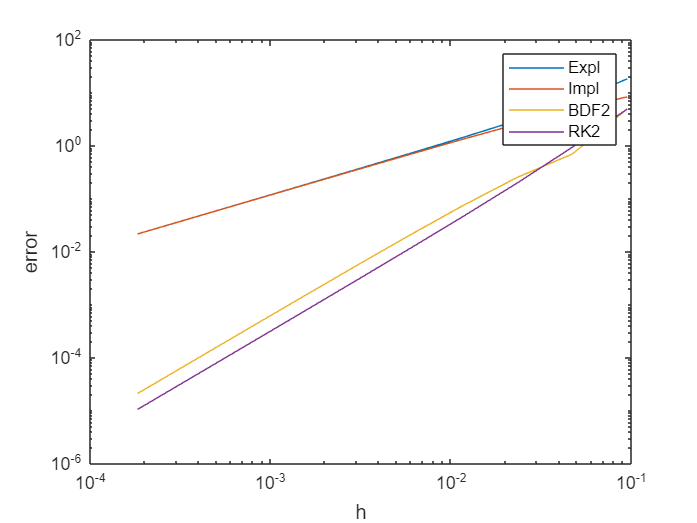

hs =T./(N-1);
loglog(hs,err_ex);
hold on
loglog(hs,err_im);
loglog(hs,err_BDF2);
loglog(hs,err_RK2);
legend(["Expl","Impl","BDF2","RK2"])
xlabel("h")
ylabel("error")
hold off

function res = RK2(x0,u0,f,h)
    k1 = h* f(x0,u0,h);
    k2 = h* f(x0 + h, u0 + k1,h);
    u1 = u0 + 1/2*(k2+k1);
    res = u1;
end
function res = fun(x,u,h)
    res = -8*u+40 * (3*exp(-x/8)+1);
end

function un2 = TwoStep(un0,un1,h,f)
    un2 = -4*un1 + 5 *un0 + h* (4*f(un1) + 2*f(un0));
end
function res = specFun(u)
    res  = -u;
end
